## Linear fit of brain weight and head size data week 1, tutorial 3

You should open the data and fill out the lines of code missing indicated by % $$$

clc
close all
clear

# Part 1 - Read the head volume vs brain mass data 

1. Load head volume vs brain mass data

filename = 'headbrain.csv';

% Read the data into MATLAB
data = readtable(filename);

**Inspect the data**

2. verify what kind of variable is contained in the opened .mat file

class(data)

ans = 'table'

3. Display the first rows - shows the different variables the table has

% Display the first few rows
head(data)

    Gender    AgeRange    HeadSize_cm_3_    BrainWeight_grams_
    ______    ________    ______________    __________________

      1          1             4512                1530       
      1          1             3738                1297       
      1          1             4261                1335       
      1          1             3777                1282       
      1          1             4177                1590       
      1          1             3585                1300       
      1          1             3785                1400       
      1          1             3559                1255       



4. Get the Gender data, Head size and BrainWeight

dgender = data.Gender;
dheadsize = data.HeadSize_cm_3_; % $$$
dbrainw = data.BrainWeight_grams_; % $$$


 5. Count how many men are in the sample (gender = 1) and how many women (gender = 2)

TIP: use == to check for the condition of elements in a vector having being equal to a specific value

TIP2: use *sum() *to add all values of a given vector. You can also sum vectors of logic values, i.e. 1 (true) or 0 (false)

bool_men   = dgender == 1; % $$$
bool_women = dgender == 2; % $$$
nmen = sum(bool_men); % $$$
nwom = sum(bool_women); % $$$
disp(nmen)

   134



disp(nwom)

   103



# Part 2 - Plot the data 

6. Plot all of the datapoints for headsize and brain weight. Plot black dots and marker size of 10

TIP: use the function *plot *you already know how to use, adding the optional argument '.b' for a different plot.

TIP2: see how to set 'MarkerSize' to 10 so that the data is more visible

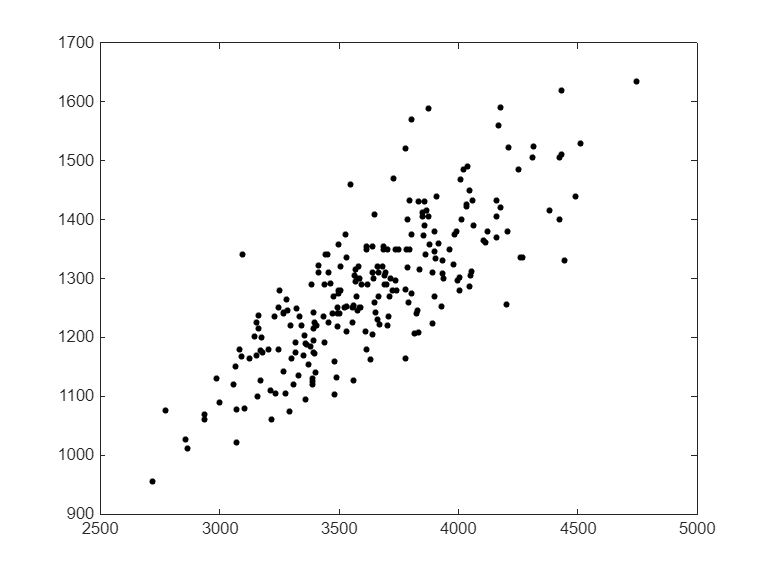

figure; plot(dheadsize, dbrainw, 'k.', 'MarkerSize', 10); % $$$

7. Plot a scatter plot of only 50 datapoints. Use the function *scatter*

Ensure there's a similar number of male and female subjects. (Doesn't have to be identical. There are many ways to do this task)

Challenge: try to get samples along the whole array, not only the first ones.

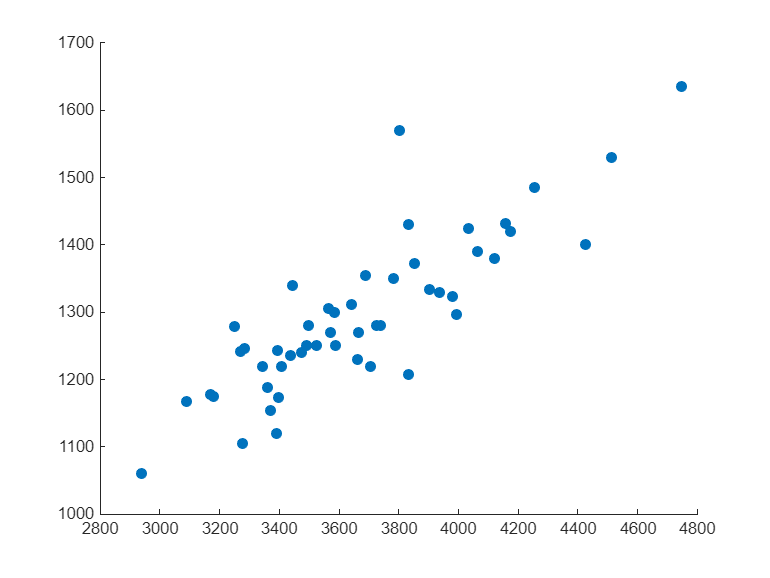

ndatap = 50; % $$$

dataidx = unique(round(linspace(1, length(dbrainw),ndatap)));% $$$
x = dheadsize(dataidx); % $$$
y = dbrainw(dataidx); % $$$

figure; scatter(x, y,"filled"); hold on

8. Plot a scatter plot of males in blue and females in red. Use the function *scatter*

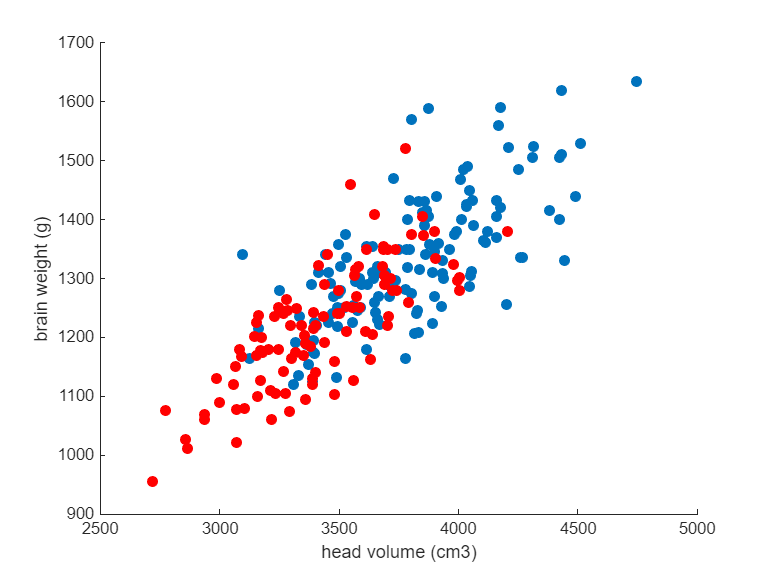

xmen = dheadsize(bool_men); % $$$
ymen = dbrainw(bool_men); % $$$
figure; scatter(xmen, ymen,"filled"); hold on

xwom = dheadsize(bool_women); % $$$
ywom = dbrainw(bool_women); % $$$
scatter(xwom, ywom,"filled", 'MarkerFaceColor', 'red');

xlabel('head volume (cm3)', 'FontSize', 10);
ylabel('brain weight (g)');

# Part 3 - Fit a linear regression to the data

9. Fit a linear regression (polynomial of only 1)

% Linear Regression using polyfit
p = polyfit(dheadsize, dbrainw, 1); % Fit degree-1 polynomial (=linear regression)


10. Identify wich value in *p* is the slope and which is the intercept

slope = p(1); % $$$
intercept = p(2); % $$$

11. Use polyval to predict the brain weights of different head sizes

TIP: *polyval*() accepts 2 inputs 1) p from polifit 2) a set of *xs* to predict *ys*

y_pred = polyval(p, x); % $$$

12. Calculate R-square to estimate the amount of variability explained by the linear model

The formula is:

*                                           R2 = 1 - (SS_residuals/SS_total) *

Where SS_residuals = sum of *(y - y_pred)^2* for all *ys*

and SS_total = sum of *(y - mean y)^2 *for all* ys*

SS_res = sum((y - y_pred).^2); % Residual sum of squares % $$$
SS_tot = sum((y - mean(y)).^2); % Total sum of squares % $$$
R2 = 1 - (SS_res / SS_tot); % $$$


13. Display the results

TIP: use num2str to transform a variable that is a number (double) into a string (char)

disp(['Slope: ', num2str(slope)])

Slope: 0.26343


disp(['Intercept: ', num2str(intercept)])

Intercept: 325.5734


disp(['R^2: ', num2str(R2)]) % $$$

R^2: 0.71784


14. Plot the linear fit and a scatter plot of the original data

Use different colors for datapoints and for the linear fit

TIP: the linear fit can be plotted using the predicted y values and the function *plot* as before

TIP2: the data points fit can be plotted using *scatter*

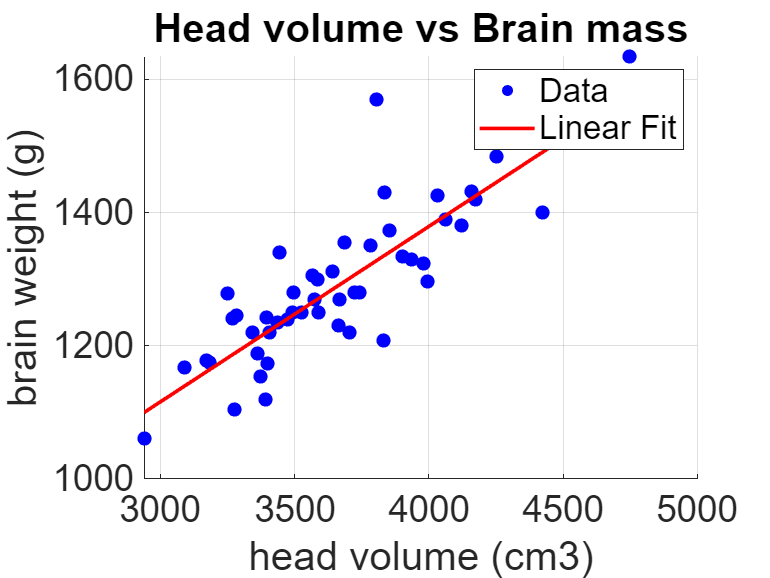

% Plot the results
figure;
scatter(x, y, 60 ,'filled','b'); % Scatter plot of original data % $$$
hold on; 
plot(x, y_pred, 'r-', 'LineWidth', 2); % Plot the regression line % $$$

xlabel('head volume (cm3)', 'FontSize', 10);
ylabel('brain weight (g)');
title('Head volume vs Brain mass')
legend('Data', 'Linear Fit');
grid on;
ax = gca; % Get the current axes
ax.FontSize = 20;

# Review:

You should have values and answers for

Part 1 - 4, 5

Part 2 - 6, 7 and 8 should produce a scatter plot of the data

Part 3 - 10, 11, 12, 13, 14 should plot the datapoints and the linear regression line